# 02686 - Scientific Computing for Differential Equations - Exam 

## 6 - Dormand-Prince 5

## Dormand-Prince 5

mu = 3;
mu2 = 20;
x0 = [1.0;1.0];
N = 10000;
t0 = 0; tf = 50;

[T,X] = dopri54FixedStepSize(@VanDerPol,0,tf,N,x0,mu);
[T1,X1] = dopri54FixedStepSize(@VanDerPol,0,tf,N,x0,mu2);

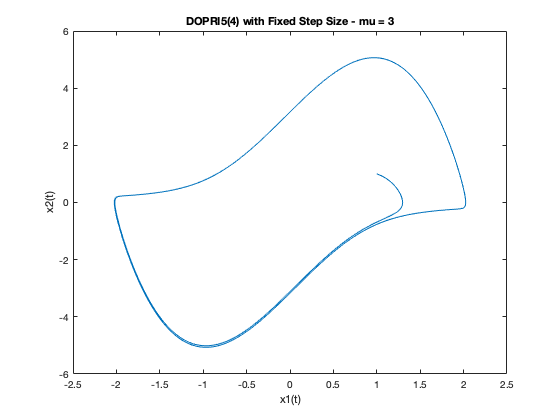

plot(X(:,1),X(:,2))
xlabel('x1(t)')
ylabel('x2(t)')
title('DOPRI5(4) with Fixed Step Size - mu = 3')

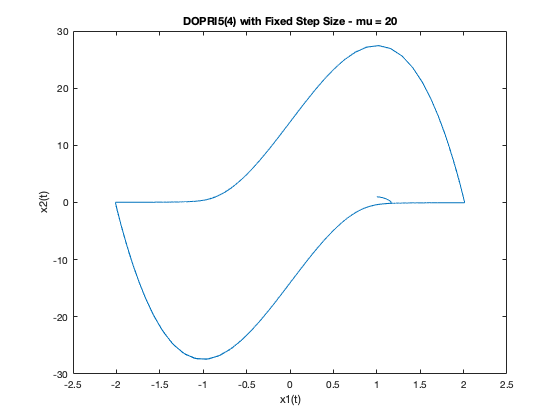


plot(X1(:,1),X1(:,2))
xlabel('x1(t)')
ylabel('x2(t)')
title('DOPRI5(4) with Fixed Step Size - mu = 20')

## For test equation

mu = 3;
mu2 = 20;
x0 = 1.0;
N = 1000;

T_final = 10;
[T,X] = dopri54FixedStepSize(@testEquationJac,0,T_final,N,x0,mu);

'testEquationJac' is not found in the current folder or on the MATLAB path, but exists in:
    /Users/MichelQu/Documents/GitHub/02686_scientific_computing
    /Users/MichelQu/Documents/GitHub/02686_scientific_computing/Ex_1

Change the MATLAB current folder or add its folder to the MATLAB path.

Error in dopri54Step (line 12)
    x1 = feval(func,t,x,varargin{:});

Error in dopri54FixedStepSize (


plot(T,X)
xlabel('Time')
title('DOPRI5(4) with Fixed Step Size - test equation')

% Local and global truncation errors
l = local_error(T,X);
plot(T,l);
title("Local error");
legend("DOPRI5");
xlabel("Time");
ylabel("Local error");

g = global_error(T,X);
plot(T,g);
title("Global error");
legend("DOPRI5");
xlabel("Time");
ylabel("Local error");
hold off;

## Runge-Kutta with Adaptative Step Size

mu = 3;
mu2 = 20;
x0 = [1.0;1.0];
N = 15000;
t0 = 0; tf = 50;

abstol = 1e-7;
reltol = 1e-7;

[T,X,info] = dopri54AdaptativeStepSize(@VanDerPol,0,tf,x0,N,abstol,reltol,mu);
[T1,X1,info1] = dopri54AdaptativeStepSize(@VanDerPol,0,tf,x0,N,abstol,reltol,mu2);

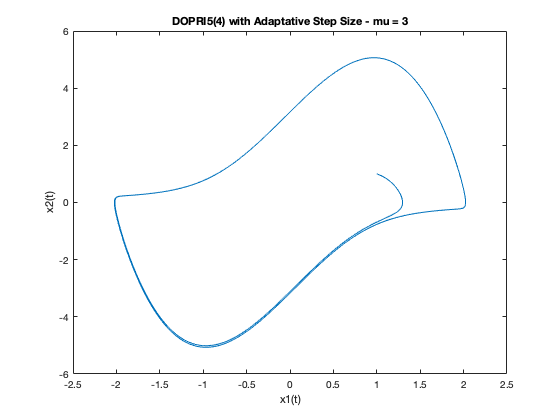

plot(X(:,1),X(:,2))
xlabel('x1(t)')
ylabel('x2(t)')
title('DOPRI5(4) with Adaptative Step Size - mu = 3')

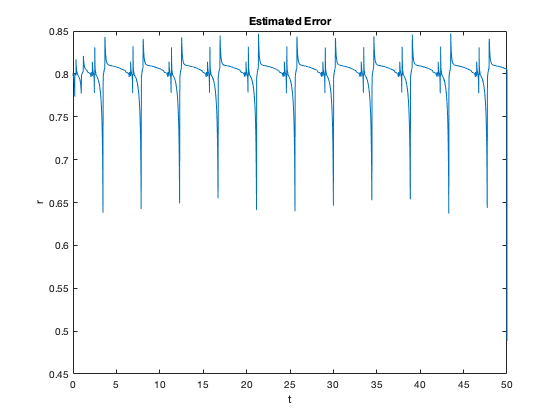


n = length(T);

plot(T(2:n),info.rr)
xlabel("t")
ylabel("r")
title("Estimated Error")

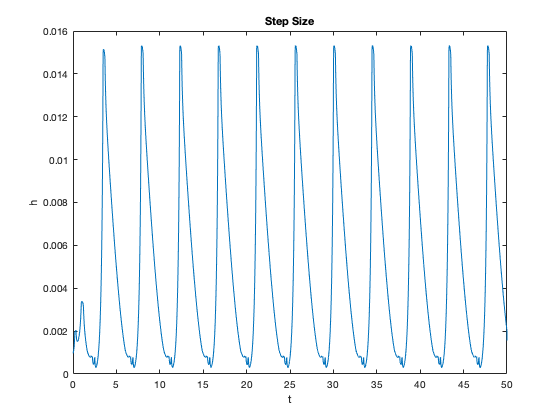


plot(T(2:n),info.hh)
xlabel("t")
ylabel("h")
title("Step Size")

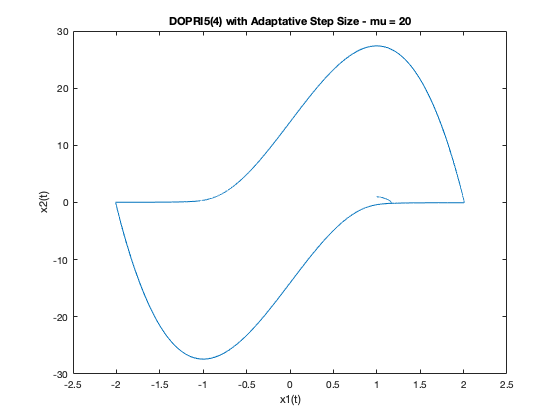

plot(X1(:,1),X1(:,2))
xlabel('x1(t)')
ylabel('x2(t)')
title('DOPRI5(4) with Adaptative Step Size - mu = 20')

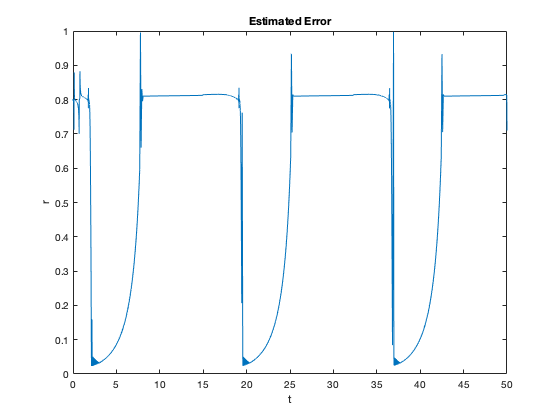


n = length(T1);

plot(T1(2:n),info1.rr)
xlabel("t")
ylabel("r")
title("Estimated Error")

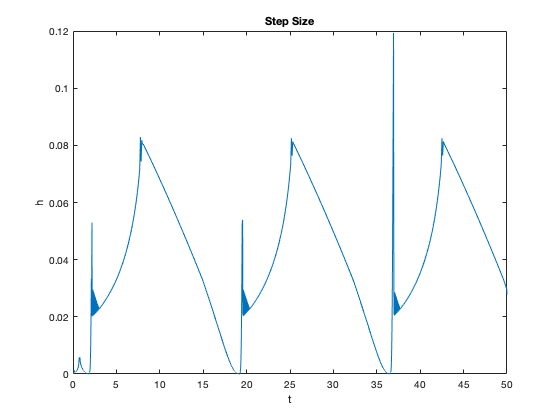


plot(T1(2:n),info1.hh)
xlabel("t")
ylabel("h")
title("Step Size")

## Solver ODE45,ODE15,DOPRI

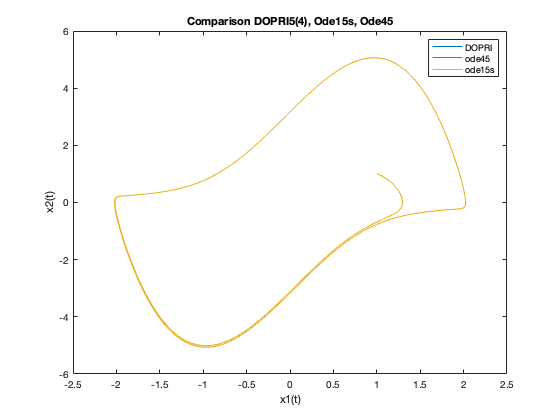

mu = 3;
x0 = [1.0; 1.0];
t0 = 0; tf = 50;

[T,X,info] = dopri54AdaptativeStepSize(@VanDerPol,t0,tf,x0,N,abstol,reltol,mu);
plot(X(:,1),X(:,2))
hold on 
options = odeset('RelTol',1.0e-6,'AbsTol',1.0e-6);
[T,X2]=ode45(@VanDerPol,[t0 tf],x0,options,mu);
plot(X2(:,1),X2(:,2))
hold on 
options = odeset('Jacobian',@JacVanDerPol,'RelTol',1.0e-6,'AbsTol',1.0e-6);
[T,X3]=ode15s(@VanDerPol,[t0 tf],x0,options,mu);
plot(X3(:,1),X3(:,2))
hold off
xlabel('x1(t)')
ylabel('x2(t)')
title('Comparison DOPRI5(4), Ode15s, Ode45')
legend('DOPRI','ode45','ode15s')

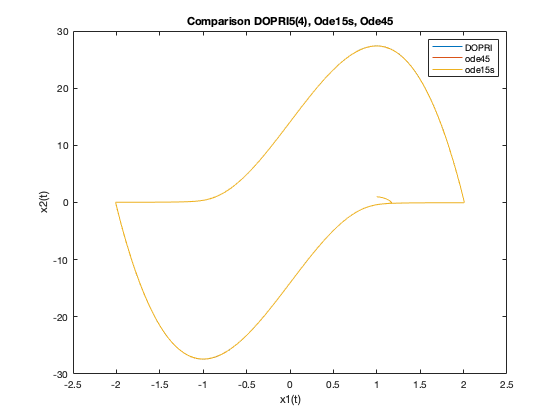

mu = 20;
x0 = [1.0; 1.0];
t0 = 0; tf = 50;

[T,X,info] = dopri54AdaptativeStepSize(@VanDerPol,t0,tf,x0,N,abstol,reltol,mu);
plot(X(:,1),X(:,2))
hold on 
options = odeset('RelTol',1.0e-6,'AbsTol',1.0e-6);
[T,X2]=ode45(@VanDerPol,[t0 tf],x0,options,mu);
plot(X2(:,1),X2(:,2))
hold on 
options = odeset('Jacobian',@JacVanDerPol,'RelTol',1.0e-6,'AbsTol',1.0e-6);
[T,X3]=ode15s(@VanDerPol,[t0 tf],x0,options,mu);
plot(X3(:,1),X3(:,2))
hold off
xlabel('x1(t)')
ylabel('x2(t)')
title('Comparison DOPRI5(4), Ode15s, Ode45')
legend('DOPRI','ode45','ode15s')

# CSTR problem

## 1-Dimensional

% Parameters
rho = 1.0;      % density
cp = 4.186;      % specific heat capacity
k0 = exp(24.6); % Arrhenius constant
EaR = 8500;     % Activation Energy
delHr = -560;   % Reaction enthalpy
V = 0.105;      % Reactor Volume
CAin = 0.8;   % Inlet Concentration of A
CBin = 1.2;   % Inlet Concentration of B
Tin = 273.65;       % Inlet Temperature


p = [rho; cp; k0; EaR; delHr; V; CAin; CBin; Tin];

